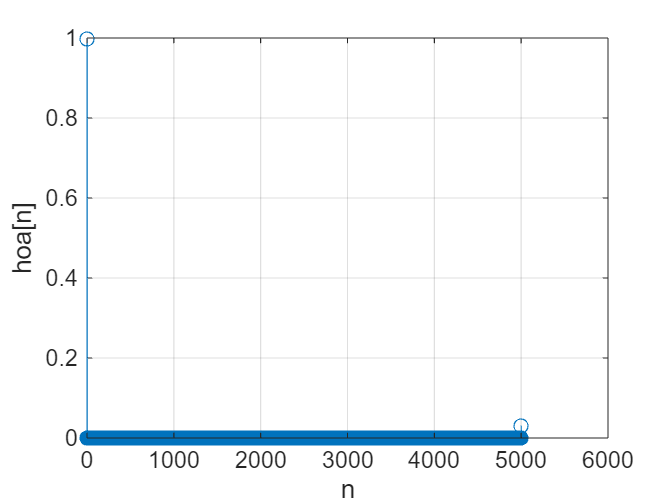

clc;
clear; 
N=1000;
alpha=0.5;
load lineup.mat
x=[1,zeros(1,1000)];
A=[1,zeros(1,999),0.5];
B=1;
d=[1,zeros(1,4000)];
he=filter(A,B,x);
her=filter(B,A,d);
hoa=conv(he,her);
figure;
stem(hoa);
grid on;
xlabel('n');
ylabel('hoa[n]');